# STEP I: Loading the data

 In this step we call the data to perform a demo of our system Identification procedure.

**Note) **Due to confidentiality of the Data, this data has no meaning, and it has nothing to do with the data addressed in the paper. However, we decided to add it here to demosntate our methodology.

load('normalizedData.mat');
%mynewTable = combinedData;
mynewTable = normalizedData;

% Here we redefine the headers in order to fix the parameters(faeatures.)
newTable.Properties.VariableNames = ["Time", "Comp_freq", "Tw_wex_out", "Tw_wex_in", "Tw_wex_delta", "Air_Temp", "TR_wex_out"];

vars= {'Comp_freq' 'Tw_wex_out' 'Tw_wex_in' 'Tw_wex_delta' 'Air_Temp' 'TR_wex_out'};
t2 = mynewTable{:,vars};
t2(isnan(t2)) = 0;
mynewTable{:,vars} = t2;
writetable(mynewTable, 'mynewTable.csv');

# STEP II: Dividing the dataset based on months:

Preprocessing and setting internal parameters

%Preprocessing
%clear temporary variables
clear opts
%mytable = table(newTable);
mymonths = month(mynewTable.Time);

Spliting the table into separate tables for each month and save them both locally (Folder of **data months**)  in the current folder and in the workspace

%main
%We specify a name for the folder.
subfolder_name = 'Data_months_year';
subfolder_path = fullfile(pwd, subfolder_name);
% Check if the subfolder exists, and if not, create it
if ~exist(subfolder_path, 'dir')
    mkdir(subfolder_path);
end

nrows = height(mynewTable);
for m = 1:12
    monthlyTable = mynewTable(mymonths == m, :);
    % Check if the table is empty or not
    if ~isempty(monthlyTable)
        % create a unique name for the table
        table_name = sprintf('Table_%04d%02d', year(monthlyTable.Time(1)), m); 
        %table_name = sprintf('table_%02d_%02d', mod(year(monthlyTable.Time),100), m);

        % set the variable names
        variable_names = {'Time', 'Comp_freq', 'Tw_wex_out','Tw_wex_in', 'Tw_wex_delta', 'Air_Temp','TR_wex_out' }; 
        disp(['Table for month ' num2str(m)]);
        disp(monthlyTable);
        %Save the related table in workspace, matfile, txt file
        assignin('base', table_name, monthlyTable);
        save(fullfile(subfolder_path, table_name), 'monthlyTable');
        writetable(monthlyTable, fullfile(subfolder_path, table_name));
    end
end

Table for month 2


          Time          Comp_freq    Tw_wex_out    Tw_wex_in    Tw_wex_delta    Air_Temp     TR_wex_out
    ________________    _________    __________    _________    ____________    _________    __________

    02/01/2023 00:00         0         0.45272       0.58289       0.47748        0.24746      0.41751 
    02/01/2023 00:01         0          0.4507       0.55615       0.51802        0.25085      0.38384 
    02/01/2023 00:02         0          0.4507       0.53743       0.54955        0.25085      0.34848 
    02/01/2023 00:03         0         0.45272       0.52941       0.56757        0.25085      0.32997 
    02/01/2023 00:04         0         0.45272       0.52406       0.57658        0.25085      0.30976 
    02/01/2023 00:05         0   

Table for month 3


          Time          Comp_freq    Tw_wex_out    Tw_wex_in    Tw_wex_delta    Air_Temp    TR_wex_out
    ________________    _________    __________    _________    ____________    ________    __________

    03/01/2023 00:00      0.74          0.5493       0.6123       0.64414       0.32203       0.85017 
    03/01/2023 00:01      0.64         0.55936      0.64439       0.61261       0.32203       0.86027 
    03/01/2023 00:02      0.22         0.54326      0.67647       0.52252       0.32203       0.86364 
    03/01/2023 00:03         0         0.50905      0.68449       0.43243       0.32203        0.8266 
    03/01/2023 00:04         0         0.50503      0.66578       0.45495       0.32203       0.50168 
    03/01/2023 00:05         0         0

# STEP III: Simulation and System Identification:

Preprocessing and setting internal parameters

%% Params
sampleTime = 0.05; % Ts
filter_wex_test = 0 ; % Set the new filter for validation part to 1 if you want to have filtered data

opt_method = 1; % See below
%change it to <2> for Gauss-Newton least squares search
%change it to <3> for Levenberg-Marquardt least squares search 
%change it to <4> for Steepest descent least squares search
%change it to <1> for the default process if you see errors

%nx=3;  % number of the state variables
%nx=4;  % number of the state variables
%nx=5;  % number of the state variables
nx=2;  % number of the state variables



Calling Simulation and System Identification for one single pair(February and March):

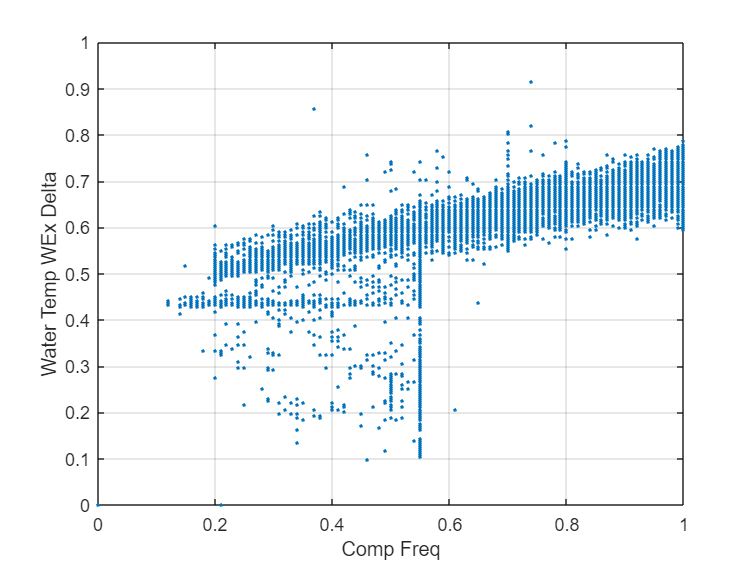

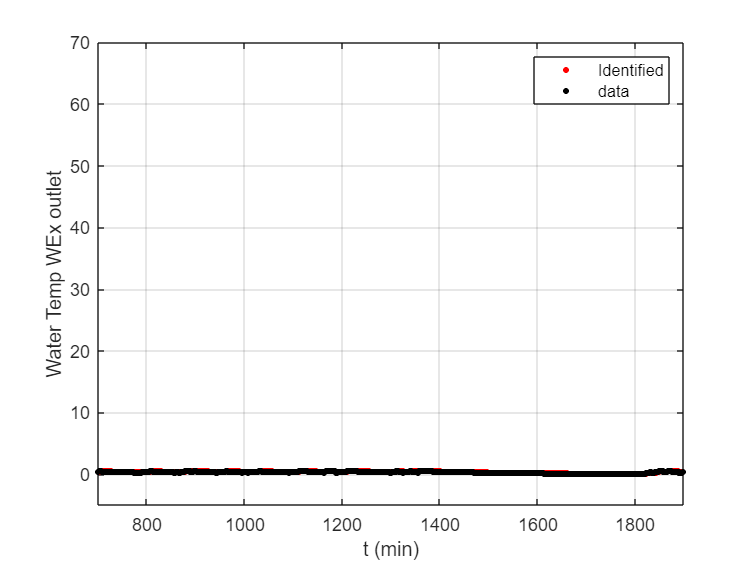

The obtained system is Controllable
The obtained system is Observable
Final Prediction Error is
   9.1679e-04

Mean squared error is
   9.1634e-04

Curve Fitting Percentage is
   77.5567



%%  Telemetry data
data4id.Comp_freq= Table_202302.Comp_freq;
data4id.Tw_wex_out= Table_202302.Tw_wex_out;
data4id.Tw_wex_in= Table_202302.Tw_wex_in;
data4id.Tw_wex_delta= Table_202302.Tw_wex_delta;
data4id.Air_Temp= Table_202302.Air_Temp;
data4id.TR_wex_out= Table_202302.TR_wex_out;

%Data for Validation
data4vl.Comp_freq2= Table_202303.Comp_freq;
data4vl.Tw_wex_out2=Table_202303.Tw_wex_out;
data4vl.Tw_wex_in2= Table_202303.Tw_wex_in;
data4vl.Tw_wex_delta2=Table_202303.Tw_wex_delta;
data4vl.Air_Temp2= Table_202303.Air_Temp;
data4vl.TR_wex_out2= Table_202303.TR_wex_out;

%Calling the comparison Function:
output_sys_m = sysid(sampleTime, filter_wex_test, opt_method, nx, data4id, data4vl,1,1);

We can specify the related SI(System Identifier) and save it for further analysis.

mpf_Table_202303 = mpf;  
save('mpf.mat', 'mpf');
mpf.Notes= 'table_202303';